В момент времени t = 0 волновая функция, описывающая квантовое состояние микрочастицы, движущейся вдоль оси x, имеет вид

Ψ(x, 0) = Aexp(-x^2/a^2 + ibx)

A, а, x - известные действительные  константы.

Определить зависимости от координаты x:

а) действительной части волновой функции

б) квадрата модуля волновой функции

Построить эти зависимости.

clc, clear, close all
datetime('now')

ans = datetime
   16-May-2023 23:25:08


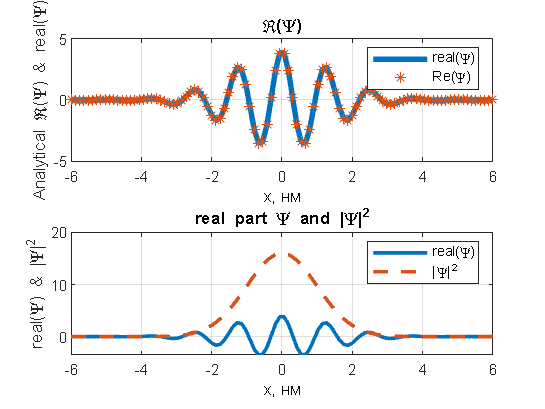


A = 4;
a = 2;
b = 5;

x = linspace(-6, 6, 100);
psi = A * exp((-x.^2 / a^2) + 1i * b * x);

subplot(2, 1, 1);
plot(x, real(psi), 'LineWidth', 3);
hold on;
scatter(x, A * exp(-x.^2 / a^2) .* cos(b * x), 'Marker', '*');
grid on;
xlabel('x, нм','Color', 'k');
ylabel('Analytical \Re(\Psi) & real(\Psi)');
legend('real(\Psi)', 'Re(\Psi)');
title('\Re(\Psi)')

subplot(2, 1, 2);
plot(x, real(psi), 'LineWidth', 2);
hold on;
plot(x, abs(psi).^2, 'LineStyle', '--', 'LineWidth', 2);
grid on;
xlabel('x, нм','Color', 'k');
ylabel('real(\Psi) & |\Psi|^2');
legend('real(\Psi)', '|\Psi|^2');
title('real part \Psi and |\Psi|^2');

Применяем формулу Эйлера к волновой функции Ψ(x, 0) = Aexp((-x^2 / a ^2) + ibx).

Получаем:

Ψ(x, 0) = Aexp(-x^2 / a ^2) * (cos(bx) + isin(bx))

Отсюда находим действительную часть Ψ:

Re(Ψ) = Aexp(-x^2 / a ^2) * cos(bx).

Пусть z = a + ib - комплексное число. Тогда |z| = sqrt(a^2 + b^2).

При использовании функции abs в mtl по отношению к комплексной функции происходит расчёт по вышеуказанной формуле.